## Семинар 12. Сингулярное и спектральное разложения матриц

Два способа факторизации матриц (представления матрицы в виде произведения других матриц)

**I)Способы представления матриц**

Прежде чем смотреть факторизации надо вспомнить общие правила обращения с матрицами

#### 1)Матрица как строка столбцов: 

$A=[\vec{a_1},..\vec{a_k}]$ матрица размером $[n\times k]$ - это строка из $k$ векторов $\vec{a_i}$ размером $[n\times1]$ кажый, 

$B=[\vec{b_1},..\vec{b_m]$ - размером  $[k\times m]$, из $m$ векторов  $\vec{b_i}$ -  размером $[k\times1]$ 

#### 2)Матрица как столбец строк: 

$A=\matrix{\vec{r_1}^T \cr \vdots \cr \vec{r_n}^T}$ , где  $ \vec{r_n}^T$- вектор-строка (для определенности будем считать, что значек $\vec$ всегда обозначает столбец), $ \vec{r_i}^T:[1\times k]$.

$B= \matrix{\vec{q_1}^T \cr \vdots \cr \vec{q_k}^T}$, $ \vec{q_i}^T:[1\times m]$

$C=AB$ - матрица размером  $[n\times k]$

clearvars
k=2

k = 2

n=3;
m=2;
a1 = sym("a1",[n 1],'real')

$$a1 = \left(\begin{array}{c} a_{11}\\ a_{12}\\ a_{13} \end{array}\right)$$

a2 = sym("a2",[n 1],'real')

$$a2 = \left(\begin{array}{c} a_{21}\\ a_{22}\\ a_{23} \end{array}\right)$$

b1 = sym("b1",[k,1],'real')

$$b1 = \left(\begin{array}{c} b_{11}\\ b_{12} \end{array}\right)$$

b2 = sym("b2",[k,1],'real')

$$b2 = \left(\begin{array}{c} b_{21}\\ b_{22} \end{array}\right)$$

A = [a1,a2];
B = [b1,b2];
r1 = A(1,:)';
q1 = B(1,:)';
q2 = B(2,:)';
r2 = A(2,:)';
r3 = A(3,:)';

### II) "Способы" умножения матриц:

Как смотреть на умножение двух матриц

1) **Классический** (суммирование) $C_{ij}=\sum_k\vec{a_k}(i)\vec{b_j}(k)$

C1 = A*B

$$C1 = \left(\begin{array}{cc} a_{11}\,b_{11}+a_{21}\,b_{12} & a_{11}\,b_{21}+a_{21}\,b_{22}\\ a_{12}\,b_{11}+a_{22}\,b_{12} & a_{12}\,b_{21}+a_{22}\,b_{22}\\ a_{13}\,b_{11}+a_{23}\,b_{12} & a_{13}\,b_{21}+a_{23}\,b_{22} \end{array}\right)$$

2) **Линейная комбинация** **столбцов** матрицы $A$ с коэффициентами - координатами столбца матрицы $B$: $C=[\vec{c_1},\dots,\vec{c_m}] = [\sum_{i=1}^{k}\vec{a_i}\vec{b_1}(i),\dots,\sum_{i=1}^{k}\vec{a_i}\vec{b_m}(i)]$

C_Columns_Combination = [a1*b1(1)+a2*b1(2),a1*b2(1)+a2*b2(2)] % комбинация столбцов

$$C\_Columns\_Combination = \left(\begin{array}{cc} a_{11}\,b_{11}+a_{21}\,b_{12} & a_{11}\,b_{21}+a_{21}\,b_{22}\\ a_{12}\,b_{11}+a_{22}\,b_{12} & a_{12}\,b_{21}+a_{22}\,b_{22}\\ a_{13}\,b_{11}+a_{23}\,b_{12} & a_{13}\,b_{21}+a_{23}\,b_{22} \end{array}\right)$$

3) **Матрица скалярных произведений (столбец строк на строку столбцов)**. Скалярное произведение строк матрицы $A$ и столбцов матрицы $B$:  $C = AB=[\matrix{\vec{r_1}^T \cr \vdots \cr \vec{r_n}^T}][\vec{b_1} \dots \vec{b_m}]=[\matrix{\vec{r_1}^T\vec{b_1}&\dots&\ \vec{r_1}^T\vec{b_m}\cr \vdots & \dots & \vdots \cr \vec{r_n}^T\vec{b_1} & \dots & \vec{r_n}^T\vec{b_m} }]$ - это точно также как умножать столбец на строку, только вместо скаляров  - вектора

C_Column_Row = [r1'*b1 r1'*b2;r2'*b1 r2'*b2;r3'*b1 r3'*b2]

$$C\_Column\_Row = \left(\begin{array}{cc} a_{11}\,b_{11}+a_{21}\,b_{12} & a_{11}\,b_{21}+a_{21}\,b_{22}\\ a_{12}\,b_{11}+a_{22}\,b_{12} & a_{12}\,b_{21}+a_{22}\,b_{22}\\ a_{13}\,b_{11}+a_{23}\,b_{12} & a_{13}\,b_{21}+a_{23}\,b_{22} \end{array}\right)$$

То есть, умножение матриц ведет себя точно также как умножение столбца на строку (внешнее произведение):

disp("column*row")

column*row


a1*b1'

$$ans = \left(\begin{array}{cc} a_{11}\,b_{11} & a_{11}\,b_{12}\\ a_{12}\,b_{11} & a_{12}\,b_{12}\\ a_{13}\,b_{11} & a_{13}\,b_{12} \end{array}\right)$$

4) **Сумма матриц (диад) внешних произведений (строка столбцов на столбец строк)** столбцов матрицы $A$ и строк матрицы $B$:


$$C = AB=[\vec{a_1},..\vec{a_k}] [ \matrix{\vec{q_1}^T \cr \vdots \cr \vec{q_k}^T}]= \vec{a_1}\vec{q_1}^T +\dots+\vec{a_k} \vec{q_k}^T$$


C_Row_Column = a1*q1' + a2*q2' % Сумма внешних произведений

$$C\_Row\_Column = \left(\begin{array}{cc} a_{11}\,b_{11}+a_{21}\,b_{12} & a_{11}\,b_{21}+a_{21}\,b_{22}\\ a_{12}\,b_{11}+a_{22}\,b_{12} & a_{12}\,b_{21}+a_{22}\,b_{22}\\ a_{13}\,b_{11}+a_{23}\,b_{12} & a_{13}\,b_{21}+a_{23}\,b_{22} \end{array}\right)$$

То есть, умножение матриц ведет себя точно также как умножение строки на столбец (скалярное произведение):

disp("Умножение столбца на строку:")

Умножение столбца на строку:


transpose(a2)*a1

$$ans = a_{11}\,a_{21}+a_{12}\,a_{22}+a_{13}\,a_{23}$$


$$C = AA^T=[\vec{a_1},..\vec{a_k}][\matrix{\vec{a_1}^T \cr \vdots \cr \vec{a_n}^T}]= \vec{a_1}\vec{a_1}^T +\dots+\vec{a_k} \vec{a_k}^T$$


Ранг каждой из диад $\vec{a_k} \vec{a_k}^T$ равен единице!

Ранг матрицы $С$ может быть равен сумме рангов этих матриц, но может быть и меньше.

A*A'

$$ans = \left(\begin{array}{ccc} {a_{11}}^{2}+{a_{21}}^{2} & a_{11}\,a_{12}+a_{21}\,a_{22} & a_{11}\,a_{13}+a_{21}\,a_{23}\\ a_{11}\,a_{12}+a_{21}\,a_{22} & {a_{12}}^{2}+{a_{22}}^{2} & a_{12}\,a_{13}+a_{22}\,a_{23}\\ a_{11}\,a_{13}+a_{21}\,a_{23} & a_{12}\,a_{13}+a_{22}\,a_{23} & {a_{13}}^{2}+{a_{23}}^{2} \end{array}\right)$$

a1*a1' + a2*a2' 

$$ans = \left(\begin{array}{ccc} {a_{11}}^{2}+{a_{21}}^{2} & a_{11}\,a_{12}+a_{21}\,a_{22} & a_{11}\,a_{13}+a_{21}\,a_{23}\\ a_{11}\,a_{12}+a_{21}\,a_{22} & {a_{12}}^{2}+{a_{22}}^{2} & a_{12}\,a_{13}+a_{22}\,a_{23}\\ a_{11}\,a_{13}+a_{21}\,a_{23} & a_{12}\,a_{13}+a_{22}\,a_{23} & {a_{13}}^{2}+{a_{23}}^{2} \end{array}\right)$$

### **III) Первая факторизация. Спектральное разложение матрицы:**

Ищем такие вектора, которые не меняют направление при действии на них квадратной матрицей размером $n\times n$

$A\vec{p}_i = \lambda_i \vec{p}_i$                                                                                                                                    (1)

$\lambda_i$ - собственные значения, $\vec{p}_i $ - собственные вектора. Если матрица несингулярна, то СВ линейно независимы и все СЗ различны. Если матрица $A$ - положительно определена, то все СЗ больше нуля, если матрица симметрична - все СВ ортогональны. $P = [\vec{p}_1 \dots \vec{p}_n]$ - матрица собственных векторов


$$AP=P [{\matrix{\lambda_1  & \dots &  0 \cr  & \ddots &  \cr 0 & \dots  & \lambda_n  } }]  =P \Lambda $$


$A  =P  \Lambda P^{-1}$ (если $A
$ - симметрична, то $P^{-1}=P^{T}$)

clearvars
  % нажмите кнопку, чтобы построить вектора
% можно посмотреть, что будет, если матрица диагональна (столбцы максимально независимы друг от друга)
% А что если матрица сингулярна? (кстати, что это...)
A = [0.221,0.699;...
    0.5,0.721] 

A =     0.2210    0.6990
    0.5000    0.7210


[Q,L] = eig(A,'vector')

Q =    -0.8723   -0.6169
    0.4890   -0.7871


L =    -0.1709
    1.1129


fig1


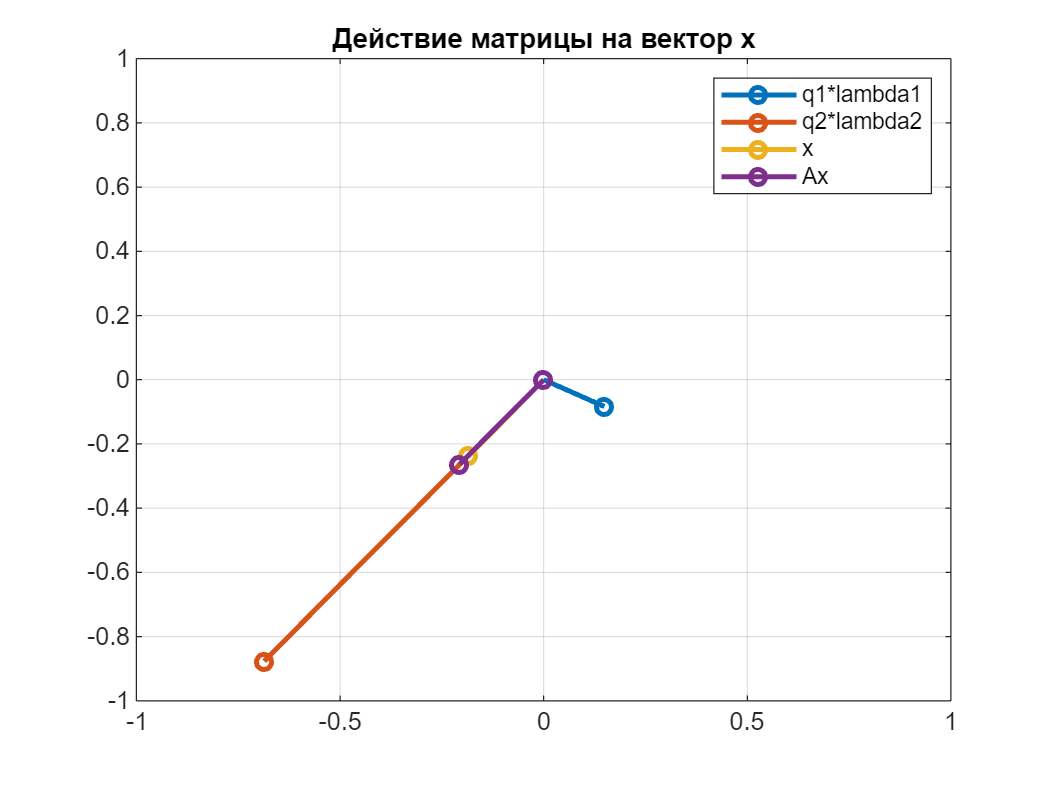

R =[-127.787;0.3];  % это вектор (в полярных координатах), на который будет действовать матрица A
% можно покрутить вектор, чтобы убедиться, что если он совпадает по направлению
% с собственным вектором, действие на него матрицы не меняет его
% направление
ang = deg2rad(R(1)); %угол вектора
module = R(2);% модуль вектора
x = [module*cos(ang);module*sin(ang)];
q1 = Q(:,1)*L(1);q2 = Q(:,2)*L(2);
draw_vector([],'Действие матрицы на вектор x',["q1*lambda1" "q2*lambda2" "x" "Ax"],"vector",q1,q2, x,A*x);

disp("угол между векторами A*x и x : "+ rad2deg(acos(x'*A*x/(norm(A*x)*norm(x)))) + " deg")

угол между векторами A*x и x : 0.34646 deg


disp("Q'*Q = ")

Q'*Q = 


disp(transpose(Q)*Q)

    1.0000    0.1532
    0.1532    1.0000



Спектральное разложение, незаменимо, когда нужны функции над матрицами:


$$A^2  =[P  \Lambda P^{-1}] [P  \Lambda P^{-1}]=P [{\matrix{\lambda_1^2  & \dots &  0 \cr  & \ddots &  \cr 0 & \dots  & \lambda_n^2  } }]P^{-1}$$


Аналогично в общем виде:


$$\Psi (A)  =P [{\matrix{\Psi(\lambda_1)  & \dots &  0 \cr  & \ddots &  \cr 0 & \dots  & \Psi( \lambda_n)  } }]P^{-1}$$


$\Psi$ - функция от матрицы, представимая в виде степенных рядов (голоморфная?)

#### IV) Вторая факторизация. Сингулярное разложение матрицы:

Ищем такой набор взаимоортогональных векторов  $v_i$ единичной длины, что действие на них матицей $A$ переводит их в другой набор взаимоортогональных векторов $u_i$:


$$A \vec{v}_i=\sigma_i \vec{u}_i$$


Или, в матричной форме:


$$AV=U\Sigma$$


Где $V=[\vec{v}_1 \dots \vec{v}_n], U=[\vec{u}_1 \dots \vec{u}_m]$ - матрицы векторов

$A=U  \Sigma  V^T$                                                                                                                                     (2)                     

$[n\times m] = [n \times m] \cdot [n \times m] \cdot [m \times n]$ - размерность в выражении (2)

В (2)   $U$ и $V$ - ортонормированные матрицы сингулярных векторов, $\Sigma$ - матрица сингулярных значений, все сингулярные значения больше нуля и отсортированы в порядке убывания

 Для ортонормированных матриц:  $V^T  V = I$, где $I$ - единичная матрица, то есть транспонированная  ортонормированная матрица является обратной к самой себе $V^T = V^{-1} $.

$\Sigma = [{\matrix{\sigma_1  & \dots &  0 \cr 0  & \ddots & 0 \cr \vdots & \dots  & \sigma_m & \cr 0 &  \dots &  0 \cr \vdots& \vdots & \vdots \cr 0 &\dots &0  } }]$-$m$ - наименьшее измерение матрицы. $\sigma_i$ - квадраты собственных значения матрицы $A^T\cdot A$, а $U$ и $V$ - матрицы собственных векторов матриц $A^T A$ и $A  A^T$ соответственно. 

Так как  недиагональная часть матрицы $\Sigma$  заполнена нулями, $\Sigma$ можно записать как  $\Sigma = [{\matrix{\sigma_1  & \dots &  0 \cr \vdots  & \ddots & \vdots \cr 0 & \dots  & \sigma_m } }]$ 

Важно, что сингулярные значения вдоль диагонали располагаюстя в порядке убывания 

Геометрический смысл компонентов сигулярного разложения на примере двумерных матриц. 

Картинка для пристального вглядывания:

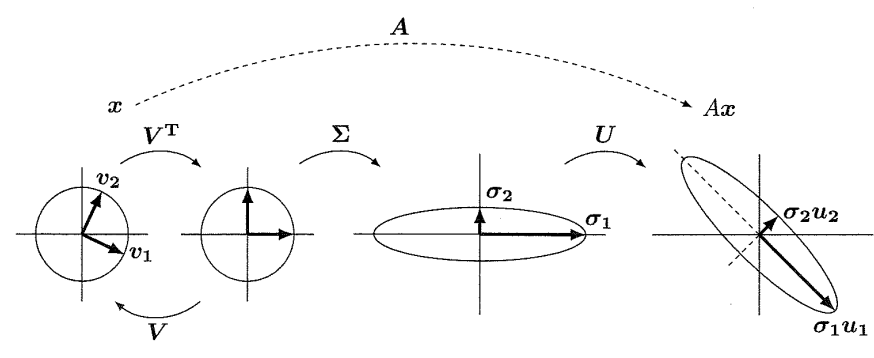

(G.Strang. Linear algebra and learning from data. MIT (2019))

Таким образом. Ортонормированные матрицы $U$ и $V$  - это операции поворота. Диагональная матрица сингулярных значений характеризует масштабирование.

Чем больше разница между сингулярными значениями, тем более вытянут эллипс


$$A=U  \Sigma V^T = \sum_{i=1}^m [\sigma_i \vec{u}_i  \vec{v}_i^T]= \sigma_1 \vec{u}_1  \vec{v}_1^T+...+\sigma_m \vec{u}_m  \vec{v}_m^T$$


, где  $\vec{u}_i$ и $\vec{v}_i$ - вектор-столбцы матриц $U$ и $V$. 

Нужно обратить внимание, что $\vec{u}_i  \vec{v}_i^T$ - это внешнее произведение, то есть матрица (рангом один) с числом строк равным числу элементов первого вектора и числом колонок равным числу элементов второго вектора. То есть, сингулярное разложение представляет матрицу как сумму матриц того же размера, при этом "вклад" каждой из этих матриц пропорционален сингулярному значению.

Похоже на сумму операторов проецирования, хм...

Сингулярное разложение дает два ортонормированных базиса:

$V$ - базис пространства строк

 $U$ - базис пространства столбцов

#### **Таким образом, сингулярное разложение, дает не только спектр, который характеризует степень сингулярности матрицы, но также и два ортонормированных базиса **$U$ и $V$ первый - в пространстве столбцов, а второй - в пространстве строк

#### Сингулярное разложение матриц в матлаб

% SVD разложение матрицы
clearvars
A = rand([5,3]) % матрица не квадратная, но для SVD это нормально!

A =     0.6361    0.8193    0.0580
    0.5716    0.0779    0.6280
    0.8202    0.8860    0.0490
    0.2193    0.3559    0.9502
    0.8683    0.7561    0.2787


[U,S,V] = svd(A)

U =    -0.4614    0.2985   -0.2764   -0.6504   -0.4457
   -0.3008   -0.4838    0.7345   -0.0731   -0.3614
   -0.5387    0.3525   -0.0355    0.7250   -0.2422
   -0.3238   -0.7362   -0.5827    0.1055    0.0496
   -0.5492    0.1026    0.2082   -0.1869    0.7807


S =     2.1442         0         0
         0    1.0064         0
         0         0    0.3706
         0         0         0
         0         0         0


V =    -0.6787    0.1292    0.7230
   -0.6572    0.3325   -0.6764
   -0.3278   -0.9342   -0.1408


disp("U*U'= ")

U*U'= 


disp(U*U') % ортонормированная матрица 

    1.0000   -0.0000    0.0000    0.0000   -0.0000
   -0.0000    1.0000   -0.0000   -0.0000         0
    0.0000   -0.0000    1.0000    0.0000         0
    0.0000   -0.0000    0.0000    1.0000   -0.0000
   -0.0000         0         0   -0.0000    1.0000



norm(U) % норма ортонормированной матрицы равна единце

ans = 1.0000

norm(A - U*S*V') % убеждаемся в правильности разложения

ans = 9.2356e-16

disp("A*v1:")

A*v1:


A*V(:,1) % действие матрицы на первый правый сингулярный вектор, дает первый левый сингулярный вектор умноженный на первое сингулярное значение

ans =    -0.9892
   -0.6450
   -1.1551
   -0.6942
   -1.1776


disp("u1*s1:")

u1*s1:


U(:,1)*S(1,1)

ans =    -0.9892
   -0.6450
   -1.1551
   -0.6942
   -1.1776


### V) Сингулярное разложение (SVD) VS Спектральное разложение (EIG)

-  **SVD** применимо для любой матрицы, **EIG** только для квадратной

- Сингулярные значения ($\sigma_1 ... \sigma_n$) всегда положительны и действительны, собственные значения  ($\lambda_1...\lambda_n$) положительны только для положительно определенной матрицы, в общем случае, даже действительной матрицы могут "уходить" в комплексное пространство

- Сингулярные вектора $\vec{u}_1 \dots \vec{u}_n$  и $\vec{v}_1 \dots \vec{v}_n$ ортогональны и нормированы на единицу (то есть $\vec{u}_i \cdot \vec{u}_i =\vec{u}_i^T\vec{u}_i=\begin{cases} \matrix{1,i =j  \cr 0,i \neq j} \end{cases}$), то есть матрицы  $U$ и $V$ - ортонормированны. Собственные вектора $\vec{p}_1 \dots \vec{p}_n$ - не нормируются и ортогональны только для симметричной матрицы

- Сингулярные значения ($\sigma_1 ... \sigma_n$) отсортированы в порядке убывания, собственные значения ($\lambda_1...\lambda_n$) не отсортированы

- Для симметричной положительно определенной матрицы (например, такой как $C=AA^T$) , сингулярные значения равны квадратам соответсвующих собственных значений, левые и правые сингулярные вектора совпадают $V=U$, сингулярные вектора совпадают по направлению с собственными векторами 

Что быстрее SVD или EIG?

svd_test = @()svd(rand(1000));
eig_test = @()eig(rand(1000));
disp("svd_test:")

svd_test:


timeit(svd_test,3)

ans = 0.1734

disp("eig_test:")

eig_test:


timeit(eig_test,3)

ans = 0.5308

disp("SVD быстрее")

SVD быстрее


Действие матрицы на правый сингулярный вектор:


$$Av_1=U  \Sigma V^T\vec{v_1} = \sum_{i=1}^m [\sigma_i \vec{u}_i  \vec{v}_i^T]\vec{v_1}=\sum_{i=1}^m [\sigma_i \vec{u}_i  \vec{v}_i^T\vec{v_1}]=\sigma_1 \vec{u}_1$$


Так как : $\sigma_i \vec{u}_i  \vec{v}_i^Tv_1=\{ \matrix{1:i=1\cr 0:i\neq1}}$ вследствие ортогональности (и ортонормированности) сингулярных векторов.

clearvars
 
%M2x2 = 0.5 - rand(2)
M2x2 = [0.786,0.417;
    0.67,0.183]

M2x2 =     0.7860    0.4170
    0.6700    0.1830


[U,S,V] = svd(M2x2)

U =    -0.7901   -0.6130
   -0.6130    0.7901


S =     1.1223         0
         0    0.1208


V =    -0.9193    0.3935
   -0.3935   -0.9193


fig2


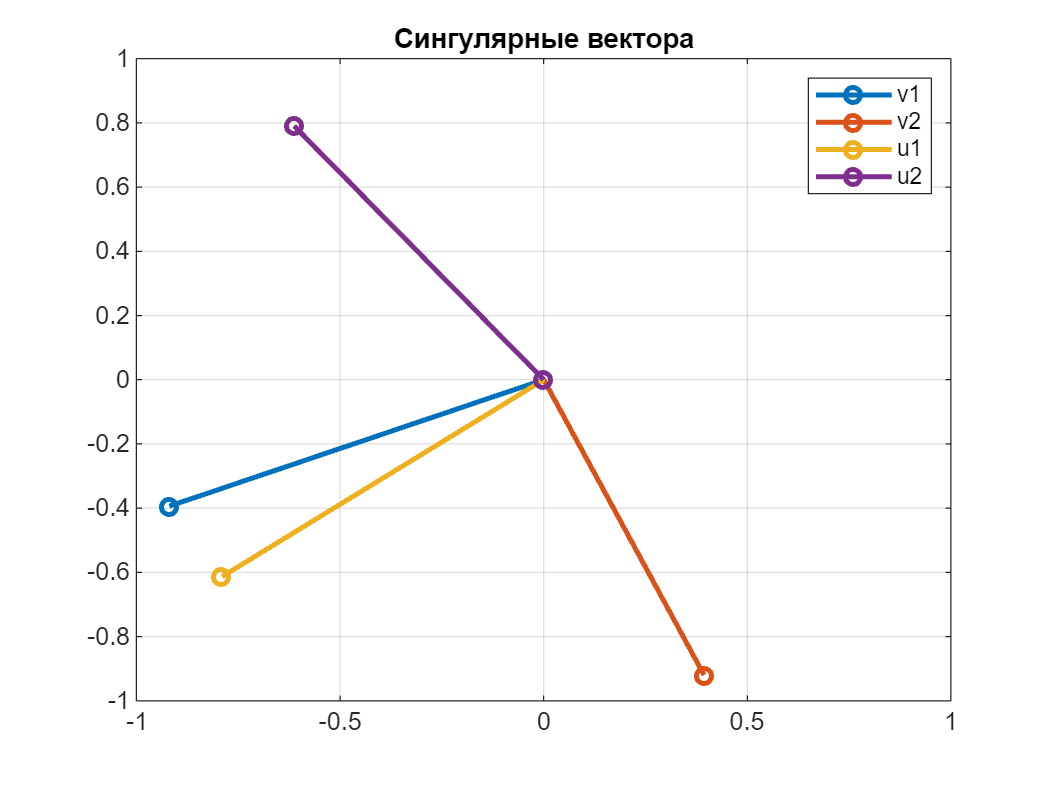

v1 =V(:,1);v2 = V(:,2);
u1 = U(:,1);u2 = U(:,2);
draw_vector([],'Сингулярные вектора',["v1" "v2" "u1" "u2"],"vector",v1,v2, u1,u2);

fig3


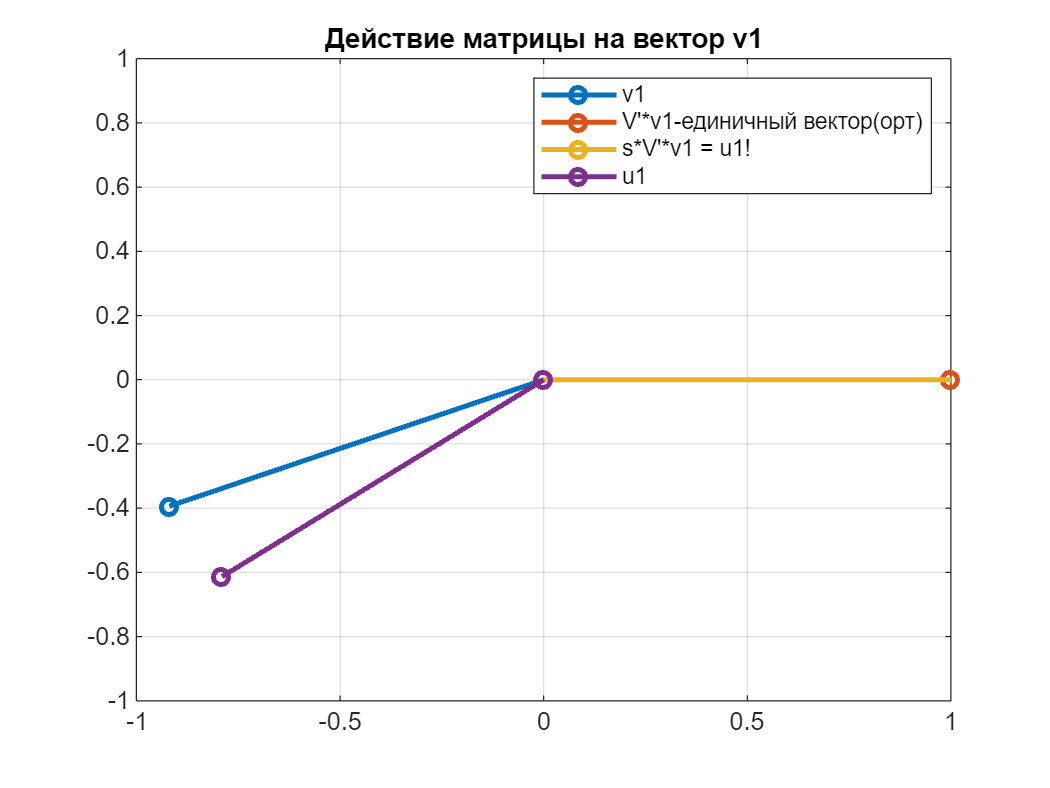

draw_vector([],'Действие матрицы на вектор v1', ...
    ["v1" "V'*v1-единичный вектор(орт)" "s*V'*v1 = u1!" "u1"],"vector",v1,V'*v1, S(1,1)*V'*v1,u1);

disp("|A*v1|/|u1| = " + norm(M2x2*v1)/norm(u1))

|A*v1|/|u1| = 1.1223


disp("S(1,1) = " + S(1,1))

S(1,1) = 1.1223


fig4


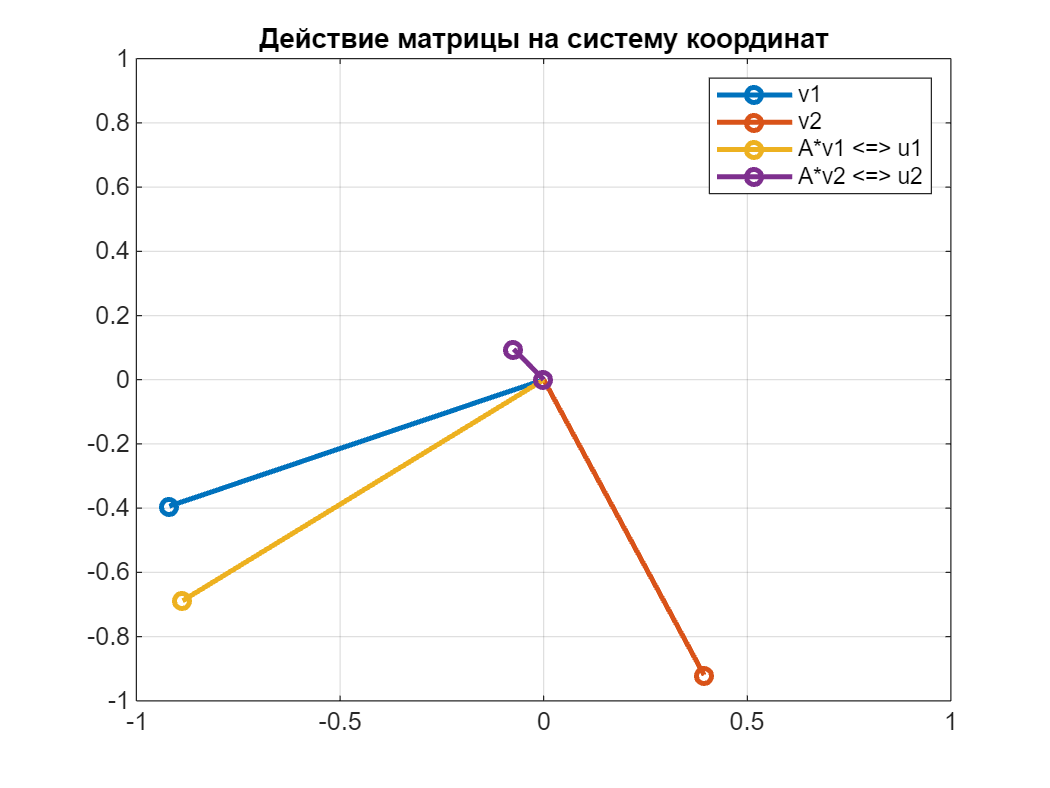

draw_vector([],"Действие матрицы на систему координат" , ...
    ["v1" "v2" "A*v1 <=> u1" "A*v2 <=> u2" ], ...
    "vector",v1,v2, M2x2*v1,M2x2*v2);

disp( "Вектор-столбцы матрицы V ортогональны: v1'*v2 = " + v1'*v2)

Вектор-столбцы матрицы V ортогональны: v1'*v2 = 0


disp( "Вектора (A*v1) и A*v2 тоже ортогональны: (A*v1)'*A*v2 = v1'*A'A*v2 = "+ transpose(M2x2*v1)*M2x2*v2)

Вектора (A*v1) и A*v2 тоже ортогональны: (A*v1)'*A*v2 = v1'*A'A*v2 = -5.5511e-17


Действие матрицы на некоторый произвольный  вектор:

Если вектор $\vec{x} $ $\in span\{V\}$, то $\vec{x}=P_{v_1}\vec{x} + ... + P_{v_m}\vec{x}=\vec{v_1}(\vec{v_1}^T\vec{x})+...+\vec{v_m}(\vec{v_m}^T\vec{x})=x_1\vec{v_1}+...x_m\vec{v_m}$ ($P_{v_i}$ - операторы проецирования)


$$A\vec{x}=U  \Sigma V^T\vec{x} = \sum_{i=1}^m [\sigma_i \vec{u}_i  \vec{v}_i^T][ \sum_{i=1}^m [ x_1\vec{v_1}+...x_m\vec{v_m}]=\sum_{i=1}^m [\sigma_i x_i \vec{u}_i  ]$$


Так как : $\sigma_i \vec{u}_i  \vec{v}_i^Tv_1=\{ \matrix{1:i=1\cr 0:i\neq1}}$ вследствие ортогональности (и ортонормированности) сингулярных векторов.

R =[75.957;1]

R =    75.9570
    1.0000


fig5


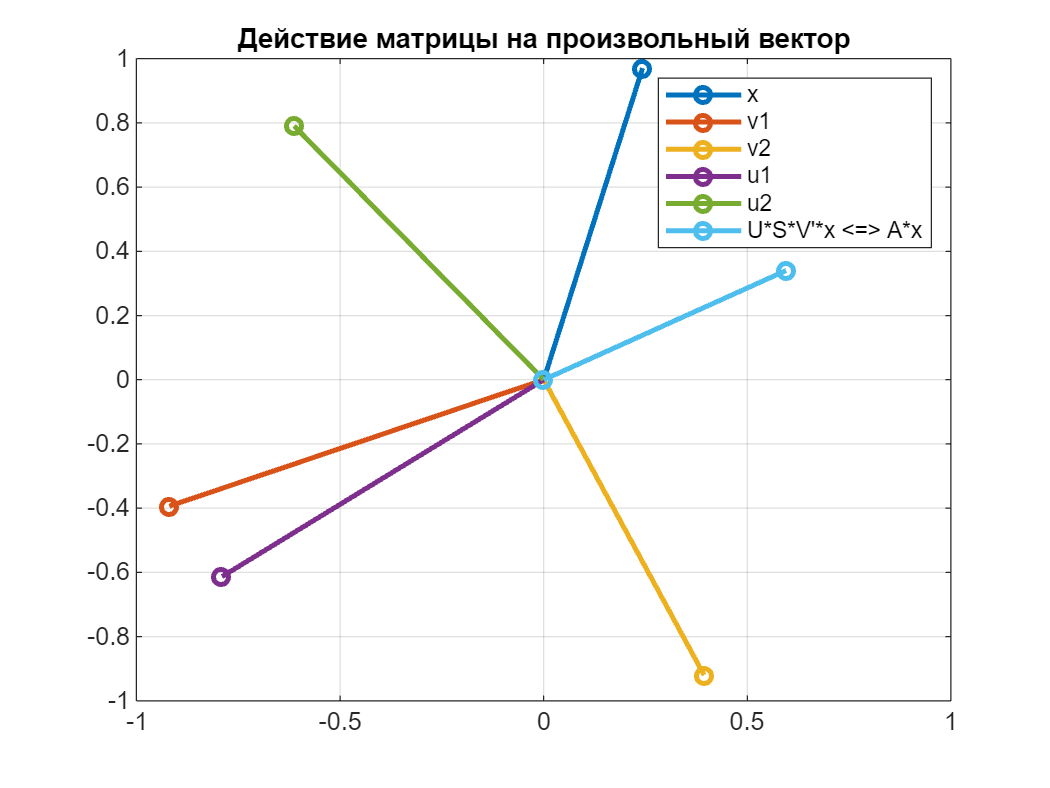

ang = deg2rad(R(1)); %угол вектора
module = R(2);% модуль вектора
x = [module*cos(ang);module*sin(ang)];
%draw_vector("Действие матрицы на произвольный вектор",["x" "v1" "v2" "u1" "u2" "V'*x" "S*V'*x" "U*S*V'*x <=> A*x"],x,v1,v2,u1,u2,v'*x, s*v'*x,u*s*v'*x);
draw_vector([],"Действие матрицы на произвольный вектор",["x" "v1" "v2" "u1" "u2" ...
    "U*S*V'*x <=> A*x"],"vector",x,v1,v2,u1,u2,U*S*V'*x);

cos_alfa = transpose(U*S*V'*x)*x;
cos_alfa = cos_alfa/(norm(U*S*V'*x)*norm(x));
disp("Скалярное произведение acos(alfa) = acos((x'*Ax)/(|x|*|Ax|)) = " + rad2deg(acos(cos_alfa)))

Скалярное произведение acos(alfa) = acos((x'*Ax)/(|x|*|Ax|)) = 46.2152


clearvars
% матрица диагональная
A = diag(rand(5,1))

A =     0.5950         0         0         0         0
         0    0.8915         0         0         0
         0         0    0.8555         0         0
         0         0         0    0.5484         0
         0         0         0         0    0.1491


svds(A)

ans =     0.8915
    0.8555
    0.5950
    0.5484
    0.1491


% матрица c большой асимметрией
A = eye(5);
A(5) = 1e6

A =            1           0           0           0           0
           0           1           0           0           0
           0           0           1           0           0
           0           0           0           1           0
     1000000           0           0           0           1


S = svds(A)

S = 1.0e+06 *

    1.0000
    0.0000
    0.0000
    0.0000
    0.0000


% Последнее сингулярное значение близко к нулю, почему так?

# Литература

- Gilbert Strang. Linear algebra and learning from data. MIT (2019)

- Gilbert Strang. Introduction to linear algebra. 2016 (Есть перевод старой версии книги : Г.Стрэнг Введение в линейную алгебру)

- youtube: канал  MIT OpenСourseWare, курс лекций MIT: 18.06SC Linear Algebra (2011)

- youtube: канал  MIT OpenСourseWare, курс лекций: MIT 18.065 Matrix methods in Data Analysis, Signal processing, and Mechine Learning (2018)

- youtube: канал AMATH 301, лектор  Nathan Kutz, лекции: The singular Value Decomposition and Principal Componen Analysis

function ax = draw_vector(ax,ttl,names,type,varargin)
% функция строит двух- и трех-мерные вектора, а также рассеянные данные из
% матрицы
% ax - оси (если пустые, то создаются новые)
% ttl - заголовок картинки
% names - имена векторов
% type:
%       "vector" - аргументы, которые передаются после интерпретируются
%                   как отдельные вектора
%       "point"  - в этом случае передается матрица в качестве аргумента и
%       столбцы матрицы строятся при помощи функций scatter и scatter3 d
%       в зависимости от размерности массива
    arguments
        ax =[]
        ttl string =strings(0,1)
        names string =strings(0,1)
        type string {mustBeMember(type,["vector" "point"])}="vector"
    end
    arguments (Repeating)
        varargin double
    end
    was_empty = isempty(ax); % это признак того, что все строится на новых осях
    if was_empty
        ax = get_next_ax();
    else
        hold(ax,"on");
        % if ~isempty(ax.Legend)
        %     leg_before = ax.Legend.String;
        % else
        %     leg_before = strings(0,1);
        % end
    end
    
    if strcmp(type,"vector")
        is_3D = numel(varargin{1})==3;
            if is_3D
                [x,y,z]  = make_xy(varargin{1});
                plot3(ax,x,y,z,'LineWidth',2,'Marker','o');
                hold on 
                for iii = 2:numel(varargin)
                        [x,y,z] = make_xy(varargin{iii});
                        plot3(ax,x,y,z,'LineWidth',2,'Marker','o');
                end
                grid on
                hold off                
            else
                [x,y]  = make_xy(varargin{1});
                plot(ax,x,y,'LineWidth',2,'Marker','o');
                hold on 
                for iii = 2:numel(varargin)
                        [x,y]  = make_xy(varargin{iii});
                        plot(ax,x,y,'LineWidth',2,'Marker','o');
                end
                grid on
                hold off
            end
            if isempty(names)||(numel(names)~=numel(varargin))
                legend(ax,string(1:numel(varargin)));
                
            else
                % if ~was_empty
                %      names= [names(:);leg_before(:)];
                % end
                legend(ax,names);
            end
            xlim(ax,[-1 1]);
            ylim(ax,[-1 1]);
            if ~isempty(ttl)
                title(ax,ttl);
            end
    else
        %data_number = numel(varargin); % число массивов данных
        is_3D = numel(varargin)==3;
        data = varargin{1};
        if size(data,2)>1
            data = transpose(data);
            is_transpose = true;
        else
            is_transpose = false;
        end
        if ~is_transpose
            for iii = 2:numel(varargin)
                data = [data,varargin{iii}];
            end
        else
            for iii = 2:numel(varargin)
                data = [data,transpose(varargin{iii})];
            end            
        end

        if is_3D
            scatter3(ax,data(:,1),data(:,2),data(:,3));
        else
            scatter(ax,data(:,1),data(:,2));
        end

    end
    if ~was_empty
            hold(ax,"off");
    end
end
function [x,y,z]  = make_xy(col)
% добавляет к координатам вектора нули так, чтобы при помощи функции plot
% строилась линия
    switch numel(col)
        case 1
            x = [col(1)];
            y = 0;
            z = 0;
        case 2
            x = [0 col(1)];
            y = [0 col(2)];
            z = zeros(1,2);
        case 3
            x = [0 col(1)];
            y = [0 col(2)];
            z = [0 col(3)];
    end
end
function [bpar,bper,ang] = projection_matrix(A,b)
% функция считает угол между вектором и пространством столбцов матрицы A
    for ii =1:size(A,2)
        A(:,ii) = A(:,ii)/norm(A(:,ii));
    end
    beta = A*transpose(A)*b;
    beta = beta/norm(beta); % нормируем вектор beta
    Pbeta = beta*transpose(beta); % оператор проектирования вектора на 
    bpar = Pbeta*b;
    bper = b-bpar;
    ang = rad2deg(acos(norm(bpar)/norm(b)));
end
function [new_ax,fig_handle] = get_next_ax(index)
% функция, которая возвращает новые оси на новой фигуре
    arguments
        index = []
    end
    persistent N;
    if isempty(index)
        if isempty(N)
            N=1;
        else
            N  = N+1;
        end
        fig_handle = figure(N);
        clf(fig_handle);
        new_ax = axes(fig_handle);
        disp("fig"+ N)
    else
        fig_handle = figure(index);
        clf(fig_handle);
        new_ax = axes(fig_handle);    
    end
end
function mem_size = mem_size_summ(varargin)
% функция считает объем несокльких переменных в памяти base workspace
    names = string(varargin);
    mem_size = 0;
    base_vars = evalin("base","whos");
    flag = arrayfun(@(X)any(strcmp(X.name,names)),base_vars);
    if ~any(flag)
        return
    end
    mem_size = sum(arrayfun(@(X)X.bytes,base_vars(flag)));
end
function folder = get_folder()
% текущая папка
folder = fileparts(matlab.desktop.editor.getActiveFilename);
end